# PRÁCTICA 8: Segmentación de Imágenes - optativa fusibles

## Enunciado

Realice un programa que admita una imagen de la carpeta .\Fuse  (de la 00 a la 20) y que determine de forma automática si el fusible es defectuoso o no.

#### Imágenes de entrada

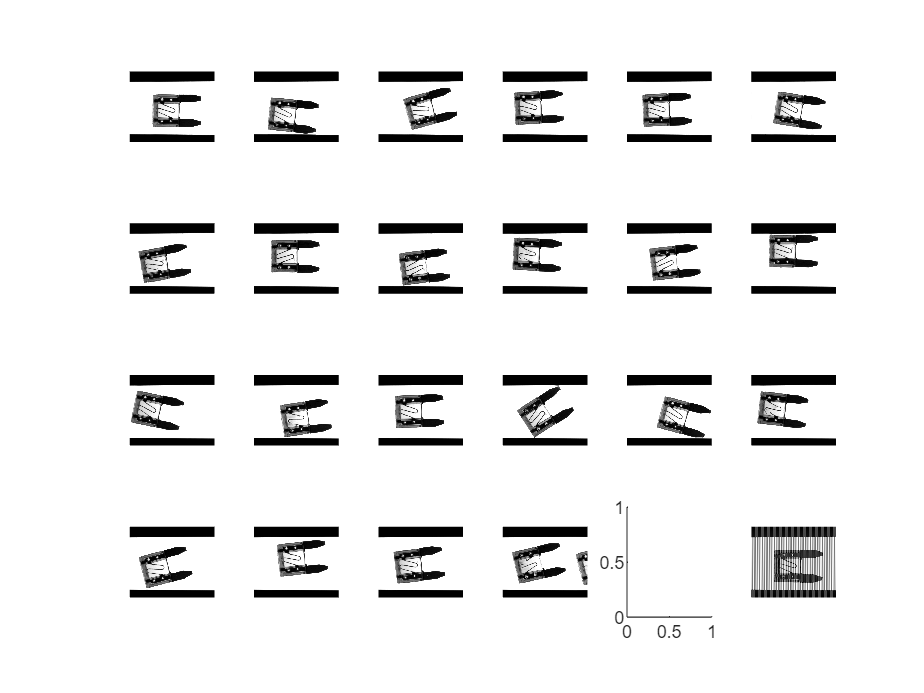

% pwd
figure
for i = 0:23
    subplot(4, 6, i+1);
    if (not(i==22))
        img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
        imshow(img);
    end
end

## Solución

### 1.- Preparación de pruebas

#### Vector de resultados esperados

Examinando la imagen definimos un vector para indicar el estado observado de cada uno de los fusibles

- 1: el fusible está bien

- 0: el fusible está roto

- -1: el fusible no existe

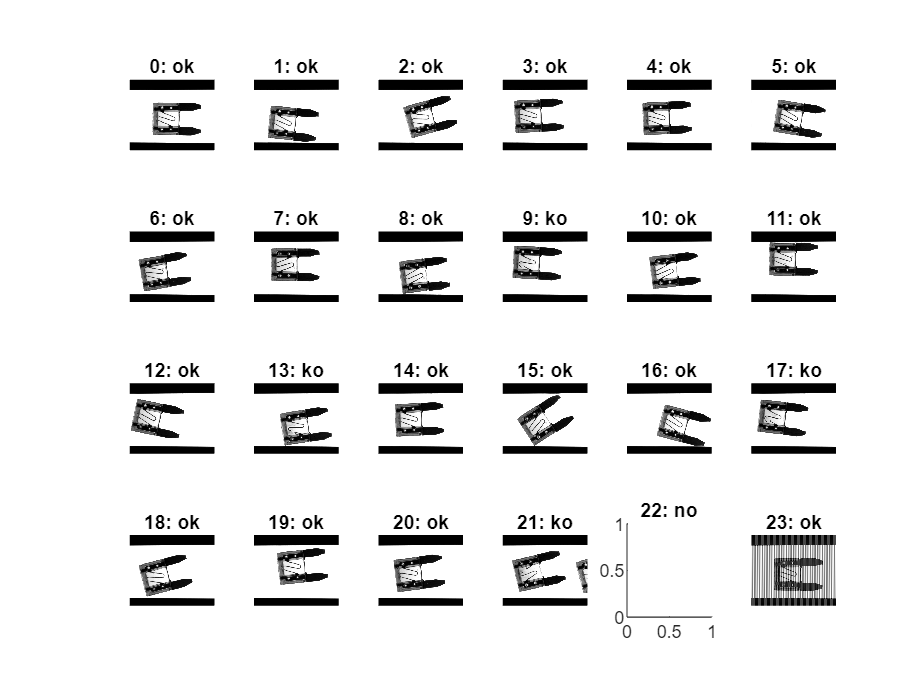

clear all;
estados = [1 1 1 1 1 1   1 1 1 2 1 1   1 2 1 1 1 2   1 1 1 2 3 1];
titulos = ['ok';'ko';'no']; % descripciones de estados
figure
for i = 0:23
    subplot(4, 6, i+1);
    if (not(i==22))
        img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
        imshow(img);        
    end
    title(sprintf("%d: %s", i, titulos(estados(i+1),:)));
end

### 2. Diesño de la solución

#### 2.a Aplicación de regiones de interés

Lo primero que hacemos es descartar la parte superior e inferior de la imagen (cinta transportadora) así como la parte izquierda; para ello utilizamos la imagen 21 que tiene dos piezas sobre la cinta

img21 = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", 21));
% help imcrop
%figure
%imshow(img)
%[J,ROI] = imcrop(img21);

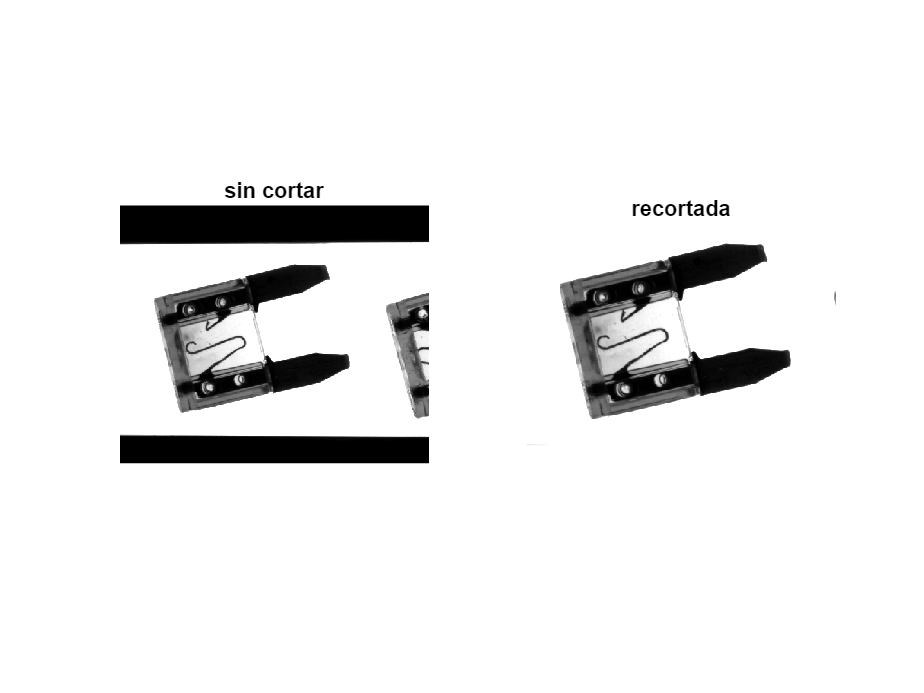

ROI = [10.51 65.51 405.98 290.98];
figure;
subplot(1,2,1); imshow(img21); title("sin cortar");
subplot(1,2,2); imshow(imcrop(img21, ROI)); title("recortada")

Comprobamos que la ROI está bien definida para todas las imágenes

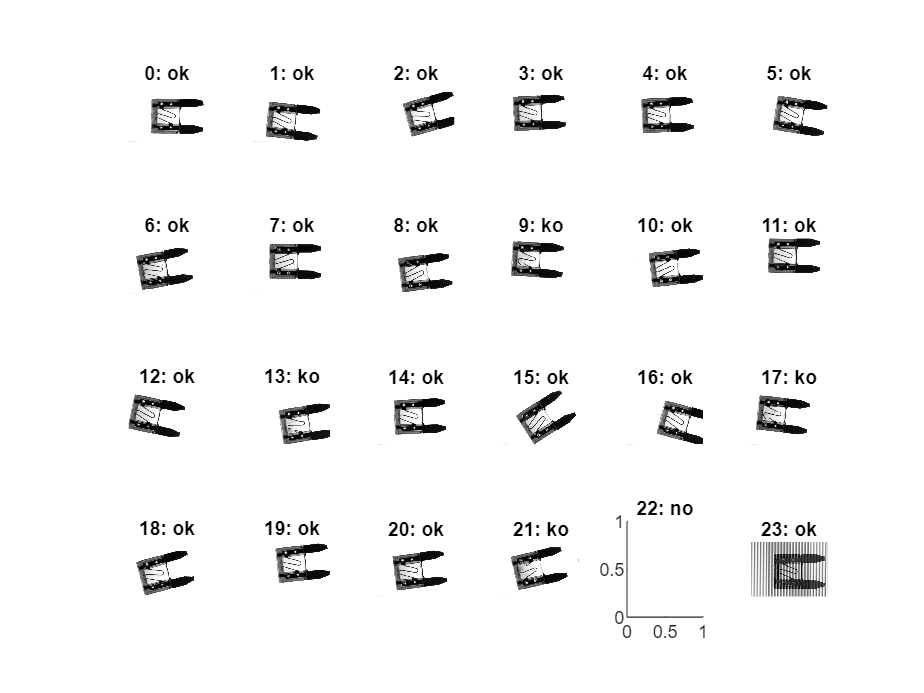

figure
for i = 0:23
    subplot(4, 6, i+1);
    if (not(i==22))
        img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
        imgc = imcrop(img, ROI); % c=crop
        imshow(imgc);
    end
    title(sprintf("%d: %s", i, titulos(estados(i+1),:)));
end

- En la imagen 16 se está truncando la parte derecha del fusible pero esto no debería ser un problema

#### 2.b Aplicación de filtado de ruido frecuencial

La imagen 23 tiene ruido frecuencial que hay que eliminar

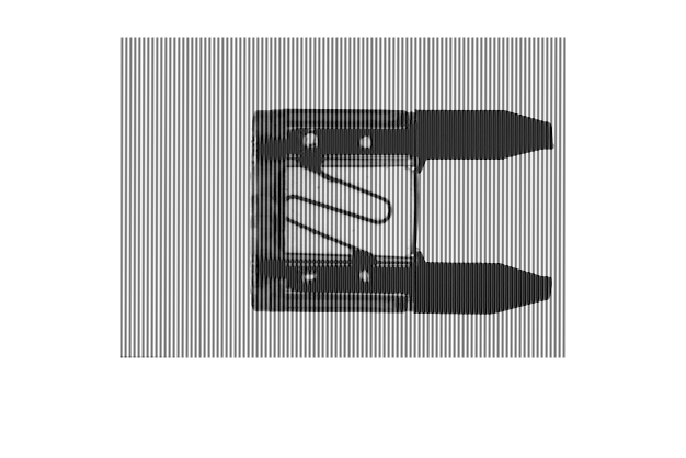

img23 = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", 23));
imgc = imcrop(img23, ROI); % c=crop
figure;
imshow(imgc);

Para ello realizamos el análisis de Fourier de la imagen

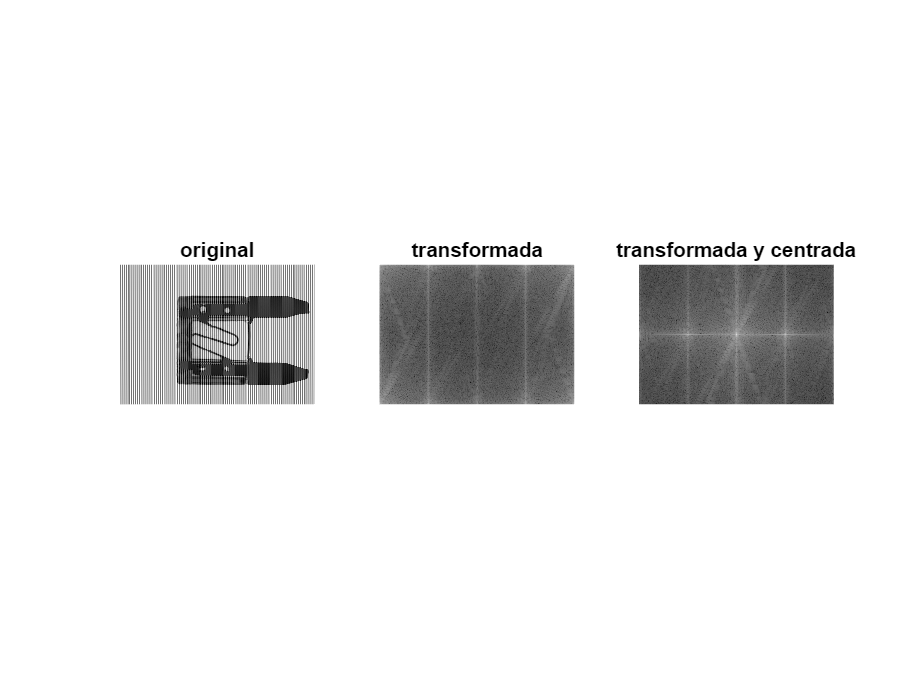

figure
subplot(1,3,1); imshow(imgc);title("original");
subplot(1,3,2); imshow(30*log10(1+abs(fft2(imgc)))/255);title("transformada");
subplot(1,3,3); imshow(30*log10(1+abs(fftshift(fft2(imgc))))/255);title("transformada y centrada")

Comprobamos las frecuencias que generan el ruido

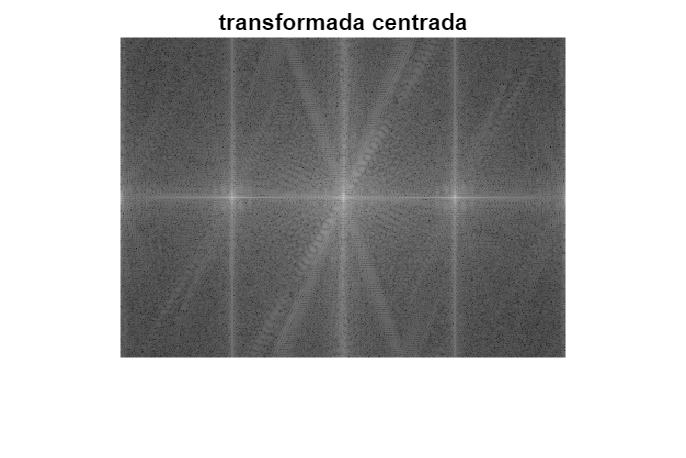

figure;
imshow(30*log10(1+abs(fftshift(fft2(imgc))))/255);title("transformada centrada");

%[x,y] = ginput(3);
x=[102 203 308];
y=[147 147 150];

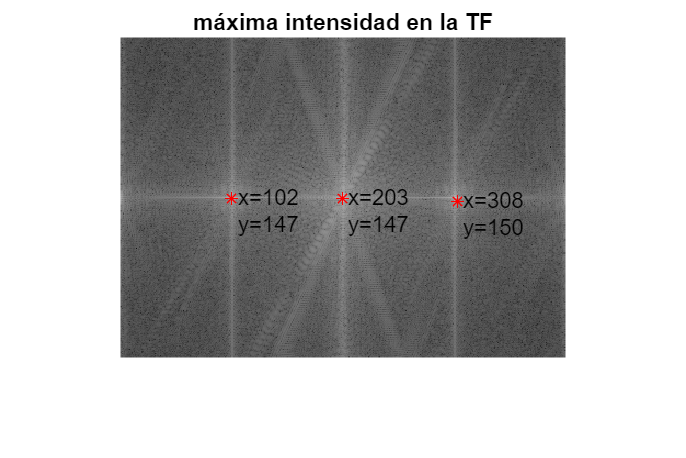

figure;
imshow(30*log10(1+abs(fftshift(fft2(imgc))))/255);
hold on;
plot(x, y, 'r*');
for i=1:3
    text(x(i),y(i)+10, sprintf(" x=%0.0f\n y=%0.0f",x(i),y(i)))
end
title("máxima intensidad en la TF");

Y diseñamos un filtro paso banda que elimine las frecuencias altas

- Realizamos diversas pruebas para que el filtro no elimine detalles importantes además del ruido

- Inicialmente probamos con un filtro paso bajo con frecuencia de corte = 50

- También probamos a subir la frecuencia de corte (óptimo en 80)

- Hemos probado a diseñar un filtro específico para las líneas verticales y la línea horizontal, pero no obtiene buenos resultados

- Finalmente optamos por ampliar la frecuencia de corte inferior y establecer una frecuencia superior

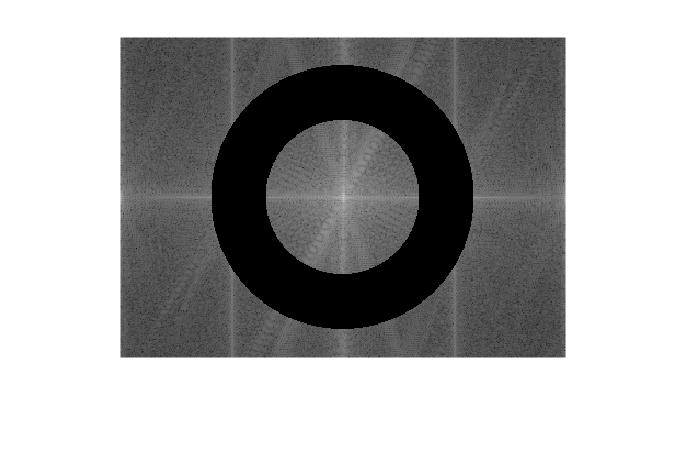

dinf = 70; % con 50 la imagen 15 pierde el puente de unión
dsup =120;
n = 1; % orden del filtro;
[tamx,tamy] = size(imgc); % Tamaño de la imagen
[xx,yy] = meshgrid(1:tamx,1:tamy);
d = sqrt((xx-tamx/2).^2+(yy-tamy/2).^2); % Distancia al centro
%ILPF = (d < dinf)
%ILPF = (((xx < 145)|(xx > 150))&((yy<95)|((yy>100)&(yy<305))|(yy>310)))';
ILPF = ((d < dinf)|(d>dsup))';

figure
imshow(ILPF.*(30*log10(1+abs(fftshift(fft2(imgc))))/255));

Comprobamos que el filtro funciona correctamente en la imagen con ruido

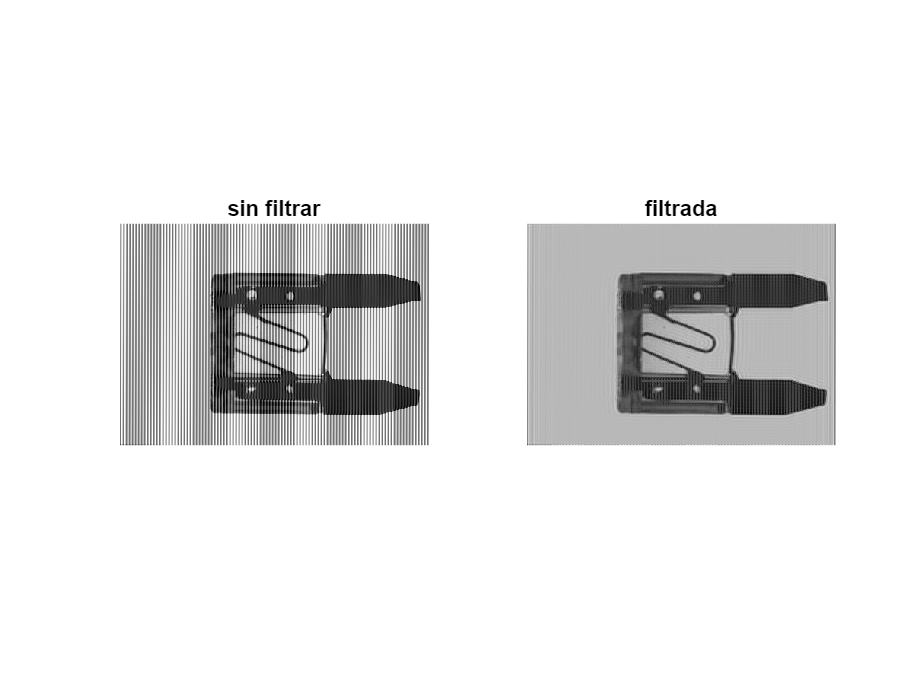

imgt = fft2(imgc);
imgf = real(ifft2(imgt .* fftshift(ILPF))/255);
figure;
subplot(1,2,1); imshow(imgc);title("sin filtrar");
subplot(1,2,2); imshow(imgf);title("filtrada");

Finalmente aplicamos el filtro a todas las imágenes para comprobar que no tiene ningún impacto negativo en el resto

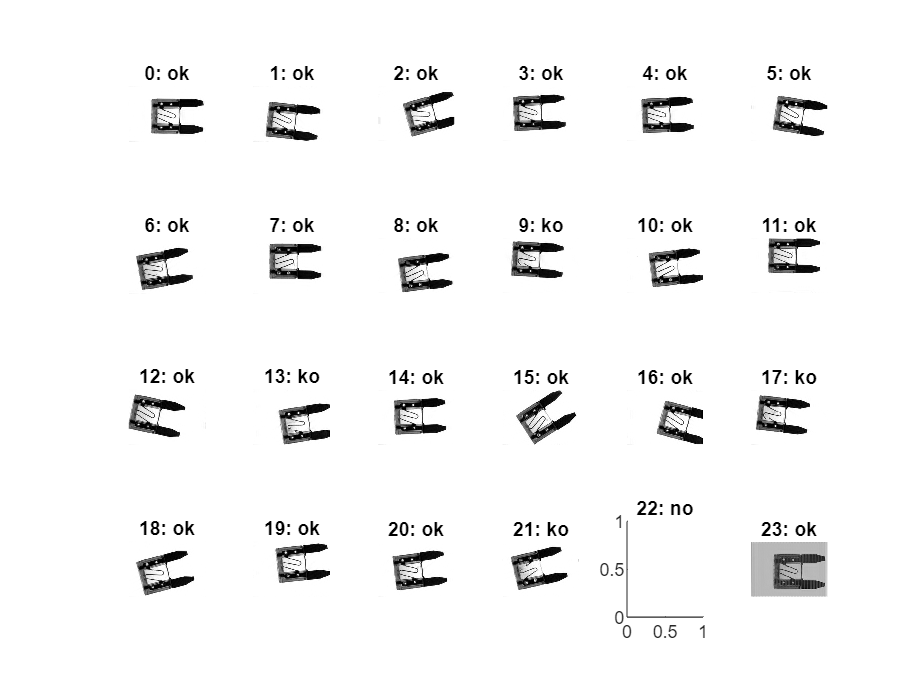

figure
for i = 0:23
    subplot(4, 6, i+1);
    if (not(i==22))
        img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
        imgc = imcrop(img, ROI); % c=crop
        imgf = real(ifft2(fft2(imgc) .* fftshift(ILPF))/255); % f=filtrada
        imshow(imgf);
    end
    title(sprintf("%d: %s", i, titulos(estados(i+1),:)));
end

#### 2.c Binarización

Binarizamos las imágenes y observamos que hay muchos detalles que dificultan extraer descriptores (p. ej., imágenes 7, 8, 10, 15)

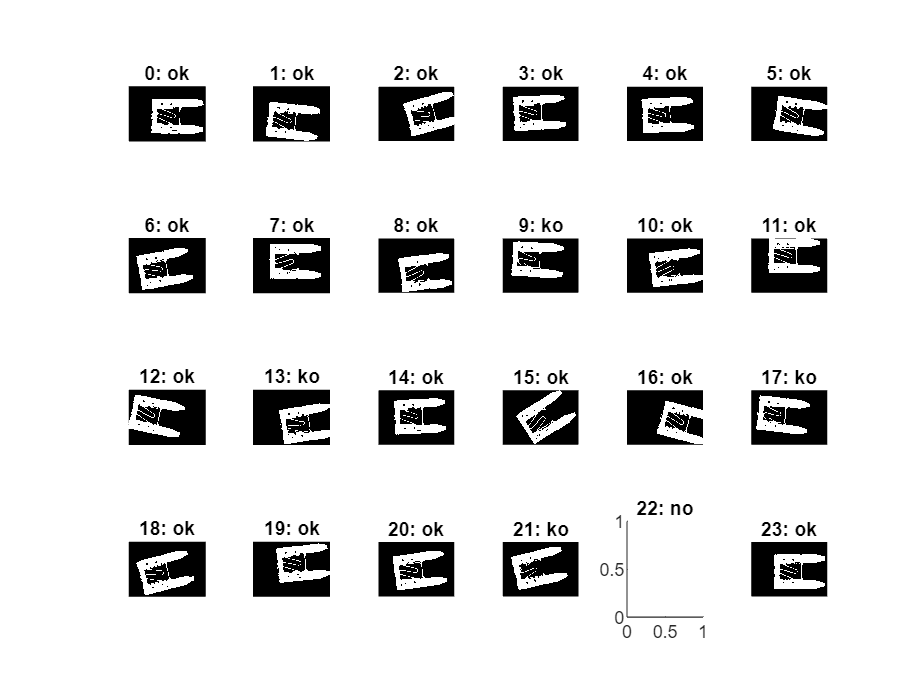

figure
for i = 0:23
    subplot(4, 6, i+1);
    if (not(i==22))
        img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
        imgc = imcrop(img, ROI); % c=crop
        imgf = real(ifft2(fft2(imgc) .* fftshift(ILPF))/255); % f=filtrada
        imshow(1-imbinarize(imgf));
    end
    title(sprintf("%d: %s", i, titulos(estados(i+1),:)));
end

Probamos con una binarización adaptativa y comprobmos que el detalle ya no se pierde

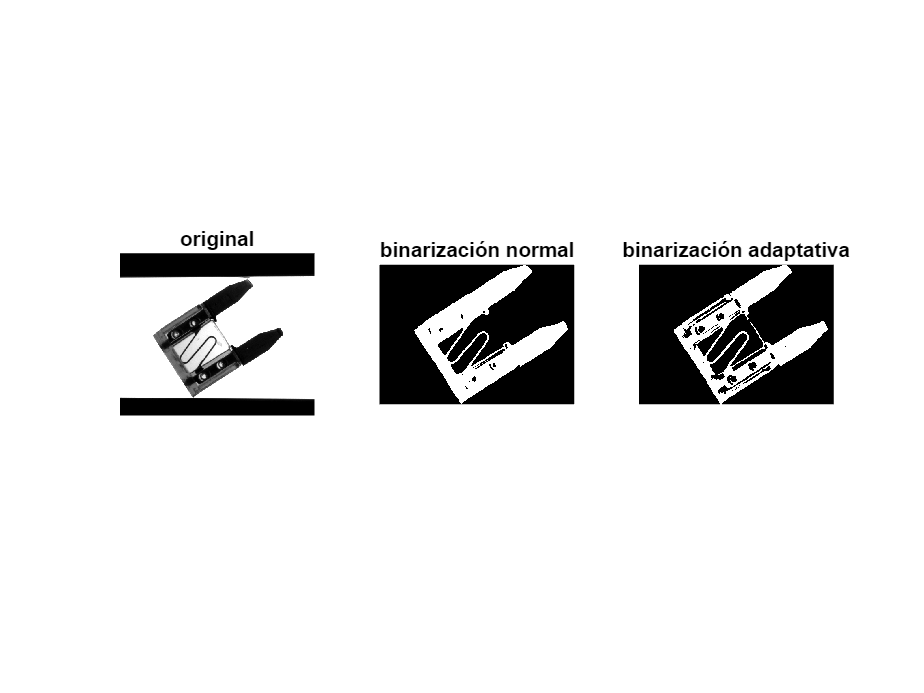

figure;
img15 = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", 15));
imgc = imcrop(img15, ROI);
imgf = real(ifft2(fft2(imgc) .* fftshift(ILPF))/255);
subplot(131); imshow(img15);title("original");
subplot(132); imshow(1-imbinarize(imgf));title("binarización normal");
subplot(133); imshow(1-imbinarize(imgf,'adaptive', Sensitivity=0.75));title("binarización adaptativa");

Aplicamos la binarización a todas las imágenes y comprobamos que no hemos perdido información relevante

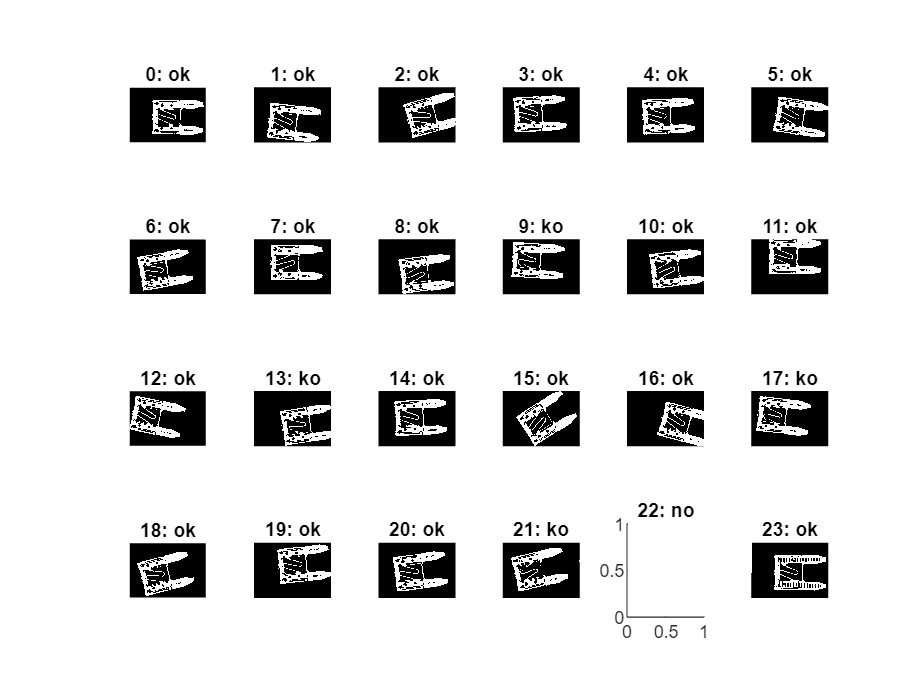

figure
for i = 0:23
    subplot(4, 6, i+1);
    if (not(i==22))
        img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
        imgc = imcrop(img, ROI); % c=crop
        imgf = real(ifft2(fft2(imgc) .* fftshift(ILPF))/255); %f=filtrada
        imgb = 1-imbinarize(imgf,'adaptive', Sensitivity=0.75); %b=binarizada
        imshow(imgb);
    end
    title(sprintf("%d: %s", i, titulos(estados(i+1),:)));
end

#### 2.d Mejora de la imagen mediante operadores morfológicos

Probamos a mejorar las imágenes con operadores morfológicos y nos aseguramos que contiene toda la información necesaria para decidir si el fusible es o no defectuoso

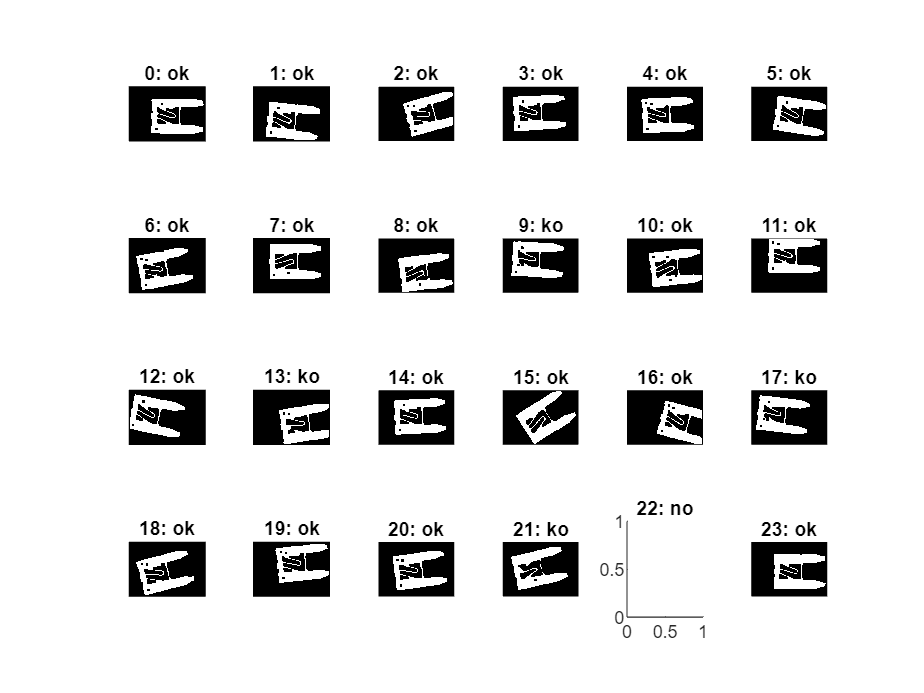

figure
for i = 0:23
    subplot(4, 6, i+1);
    if (not(i==22))
        img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
        imgc = imcrop(img, ROI); % c=crop
        imgf = real(ifft2(fft2(imgc) .* fftshift(ILPF))/255); %f=filtrada
        imgb = 1-imbinarize(imgf,'adaptive', Sensitivity=0.70); %b=binarizada
        imgm = bwmorph(imgb, 'dilate', 5); % m=mejorada
        imgm = bwmorph(imgm, 'erode', 5);
        imshow(imgm);
    end
    title(sprintf("%d: %s", i, titulos(estados(i+1),:)));
end

#### 2.e Extracción de descriptores

Invertimos la imagen resultante y obtenemos las regiones conectadas

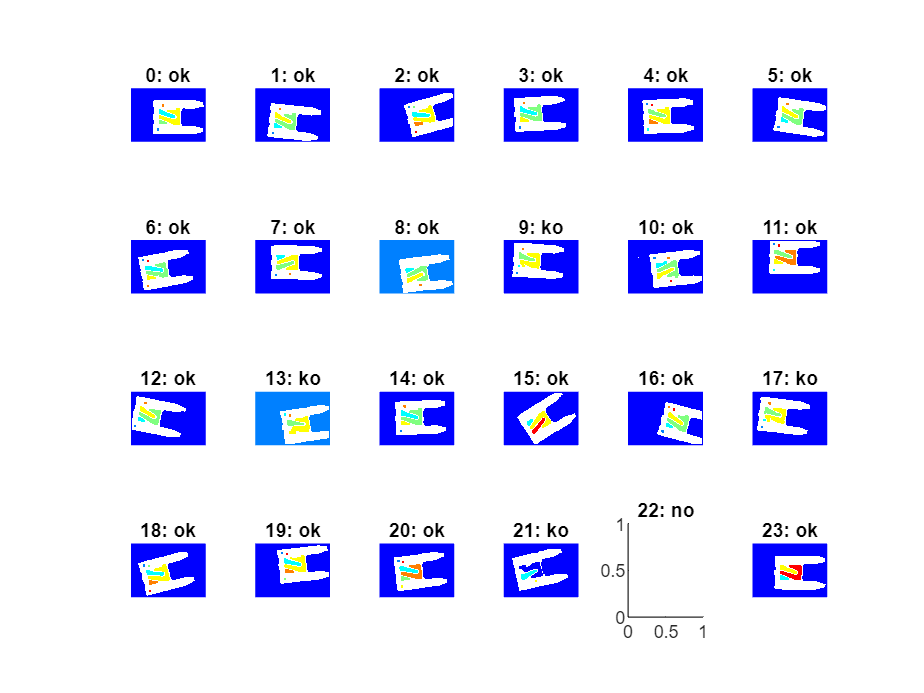

figure
for i = 0:23
    subplot(4, 6, i+1);
    if (not(i==22))
        img = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
        imgc = imcrop(img, ROI); % c=crop
        imgf = real(ifft2(fft2(imgc) .* fftshift(ILPF))/255); % f=filtrada
        imgb = 1-imbinarize(imgf,'adaptive', Sensitivity=0.70); % b=binarizada
        imgm = bwmorph(imgb, 'dilate', 5); % m=mejorada
        imgm = bwmorph(imgm, 'erode', 5);
        imge = bwlabel((1-imgm)); % l=etiquetada
        imshow(label2rgb(imge));
    end
    title(sprintf("%d: %s", i, titulos(estados(i+1),:)));
end

Observamos que, cuando el fusible es correcto, tiene que haber 3 superficies (aparte del fondo) con un área significtivamente mayor que el área de los huecos circulares. 

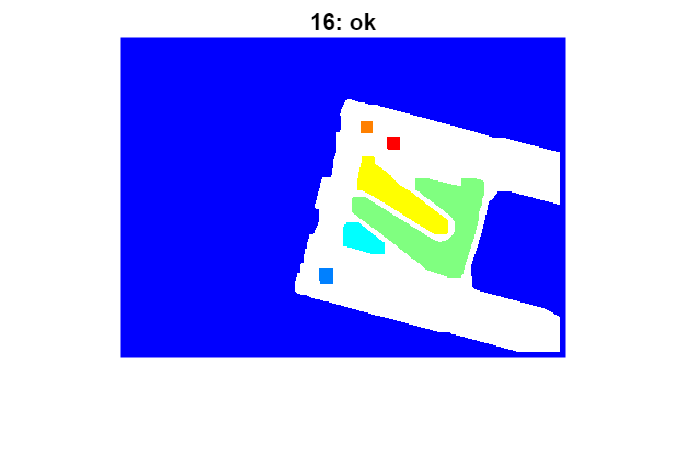

figure
i=16;
img16 = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i));
imgc = imcrop(img16, ROI); % c=crop
imgf = real(ifft2(fft2(imgc) .* fftshift(ILPF))/255); % f=filtrada
imgb = 1-imbinarize(imgf,'adaptive', Sensitivity=0.70); % b=binarizada
imgm = bwmorph(imgb, 'dilate', 5); % m=mejorada
imgm = bwmorph(imgm, 'erode', 5);
imge = bwlabel((1-imgm)); % e=etiquetada
imshow(label2rgb(imge));
title(sprintf("%d: %s", i, titulos(estados(i+1),:)));

En el peor caso, el fusible 16, la superficie significativa (en la zona del hilo del fusible) más pequeña tiene 763 pixeles.

pro = regionprops (imge,'Area');
pro.Area

ans = 83838

ans = 179

ans = 763

ans = 4981

ans = 2120

ans = 121

ans = 143

Por tanto, usamos como criterio de clasificación el número de regiones con un área de más de 700 pixeles, que debe ser igual a 4 para que el fusible sea correcto

sum([pro.Area]>700)

ans = 4

### 3. Programación

Diseñamos una función para comprobar si el fusible es correcto

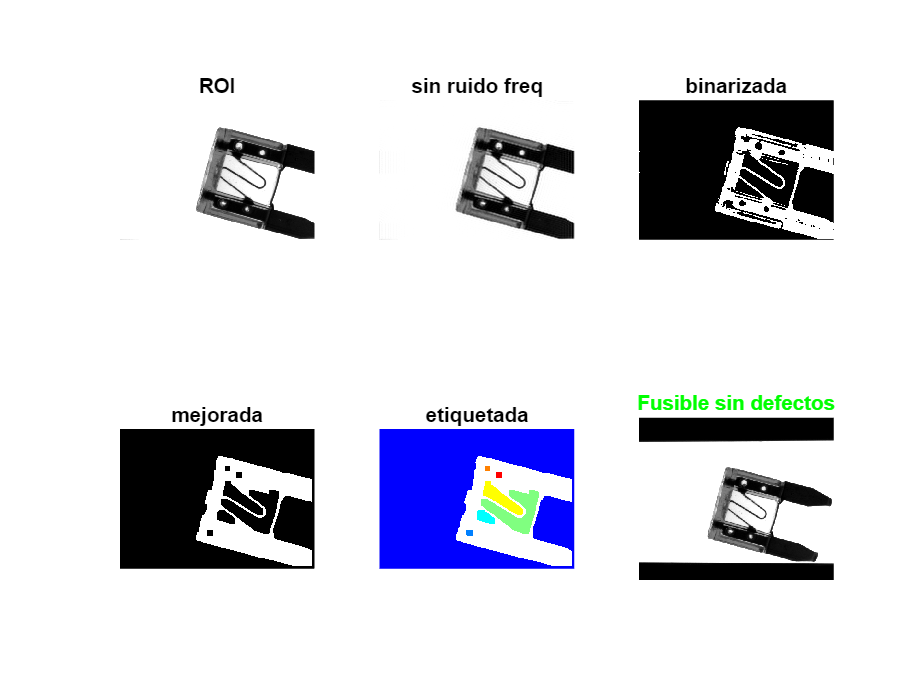

ans = logical
   1


clear all;
img16 = imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", 16));
FusibleEsCorrecto(img16)

### 4. Pruebas

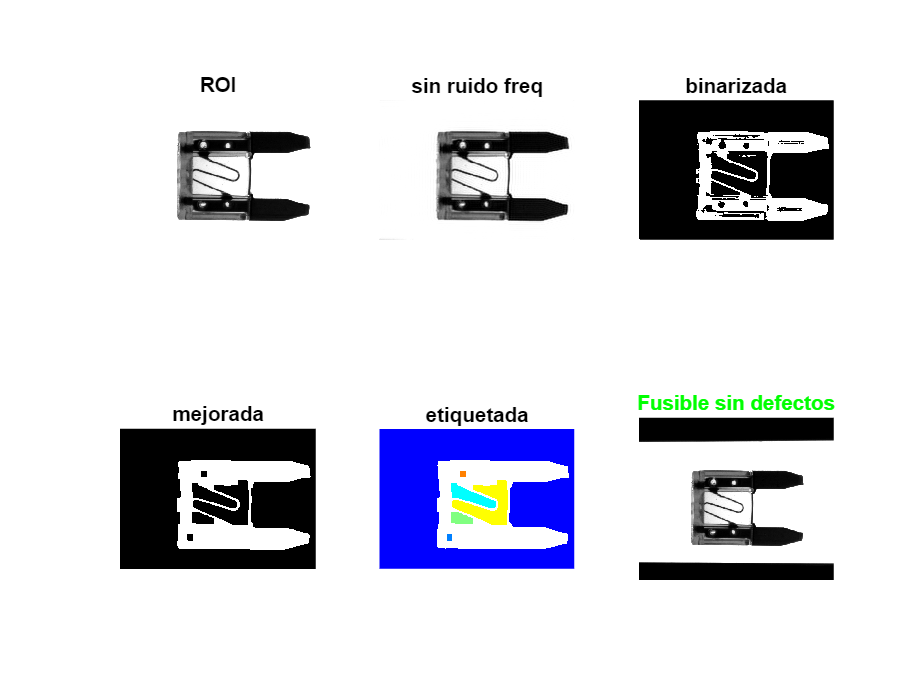

ans = logical
   1


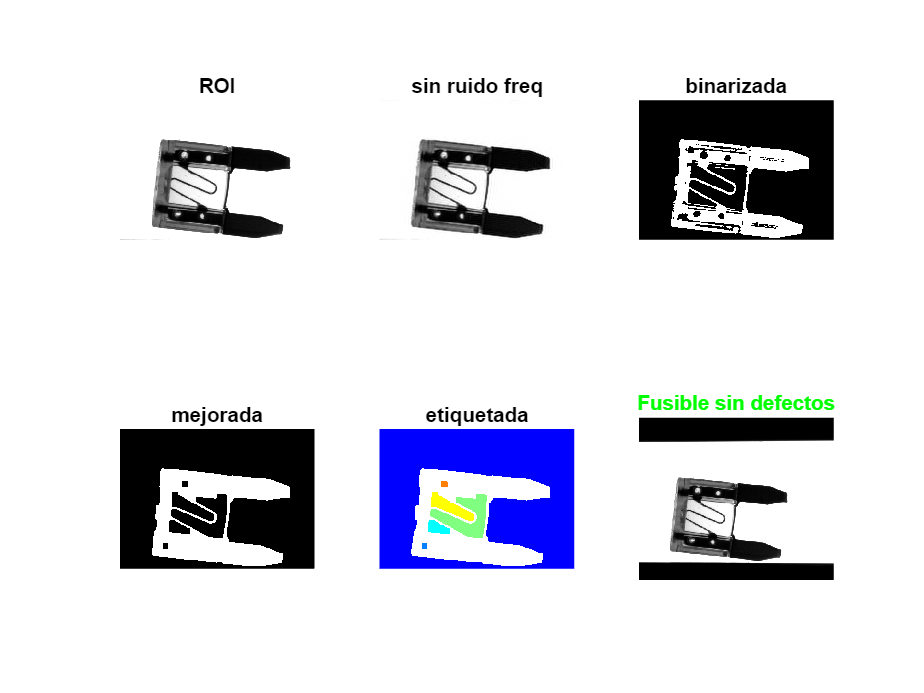

ans = logical
   1


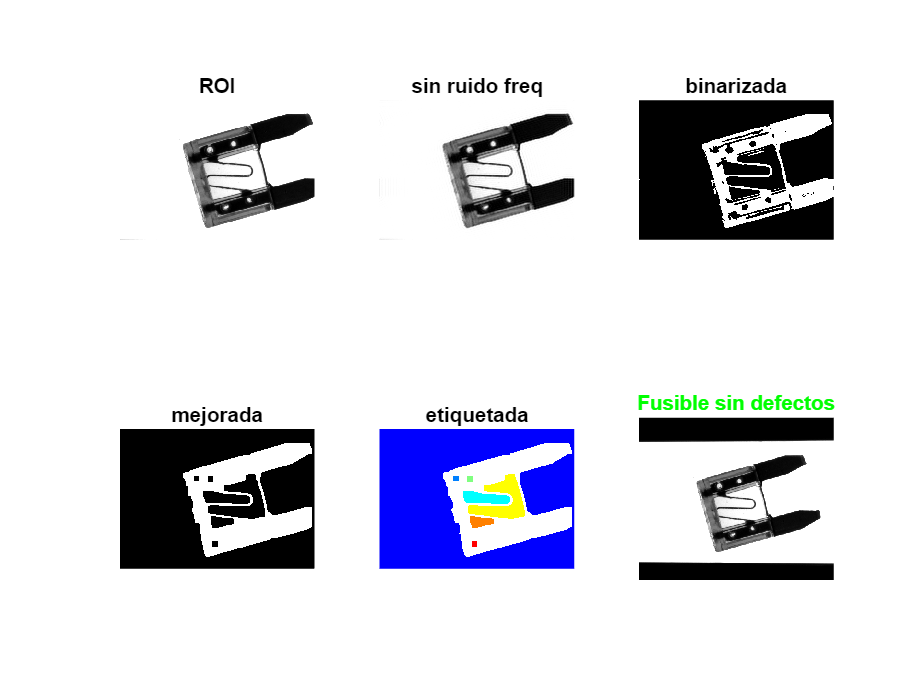

ans = logical
   1


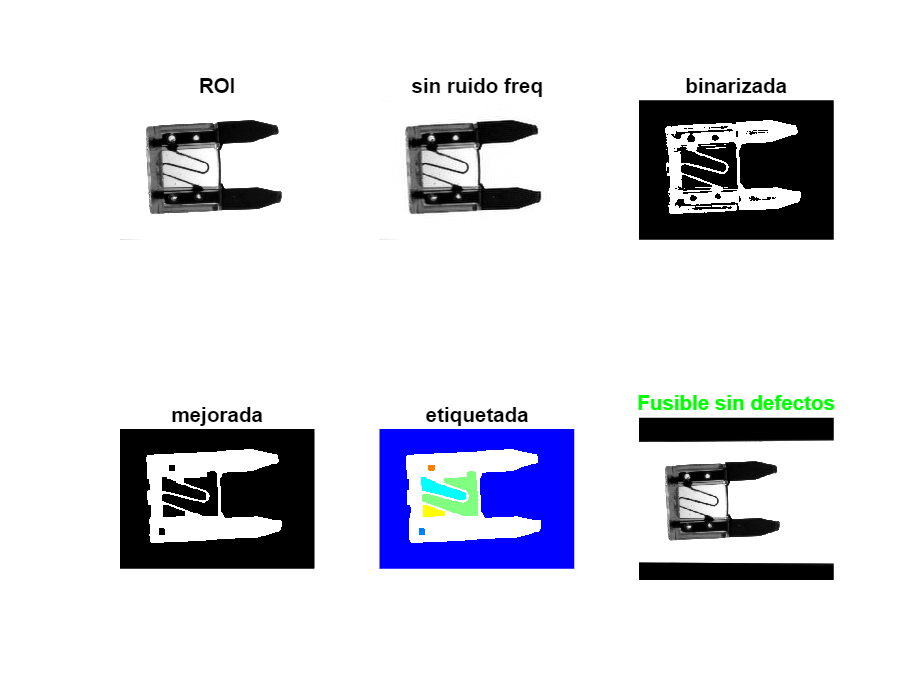

ans = logical
   1


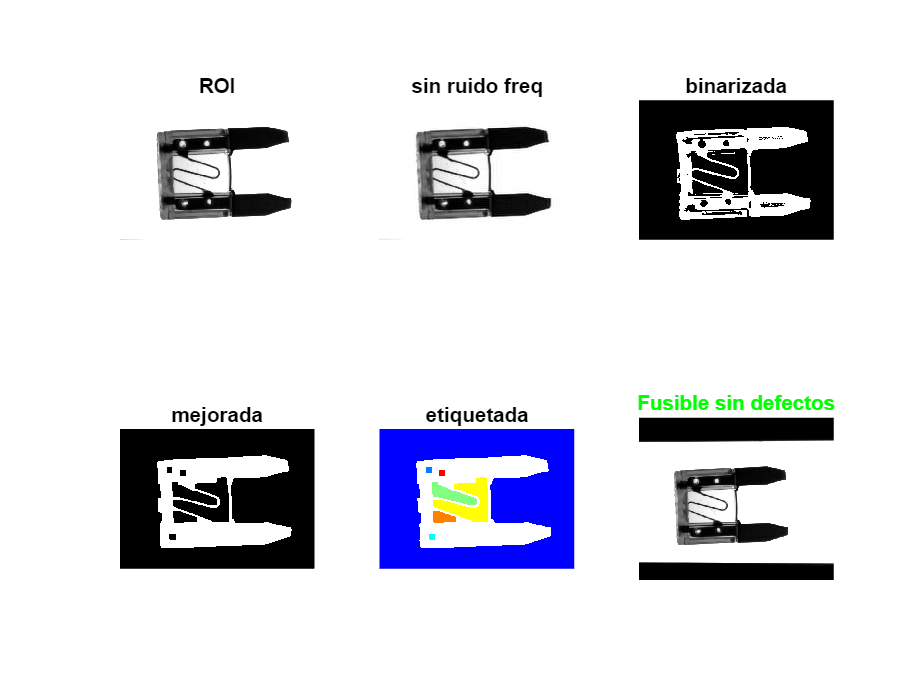

ans = logical
   1


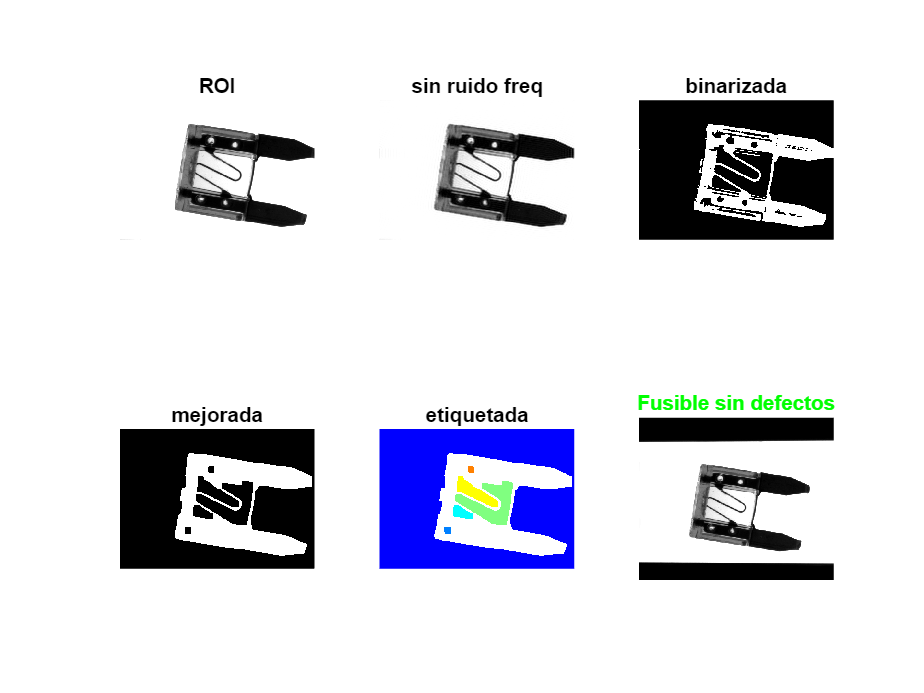

ans = logical
   1


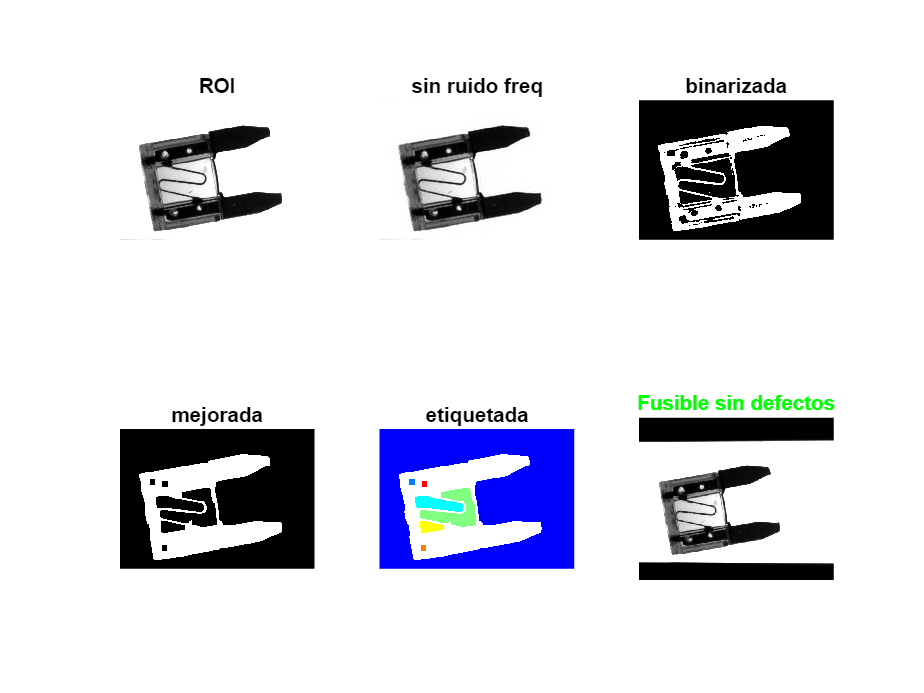

ans = logical
   1


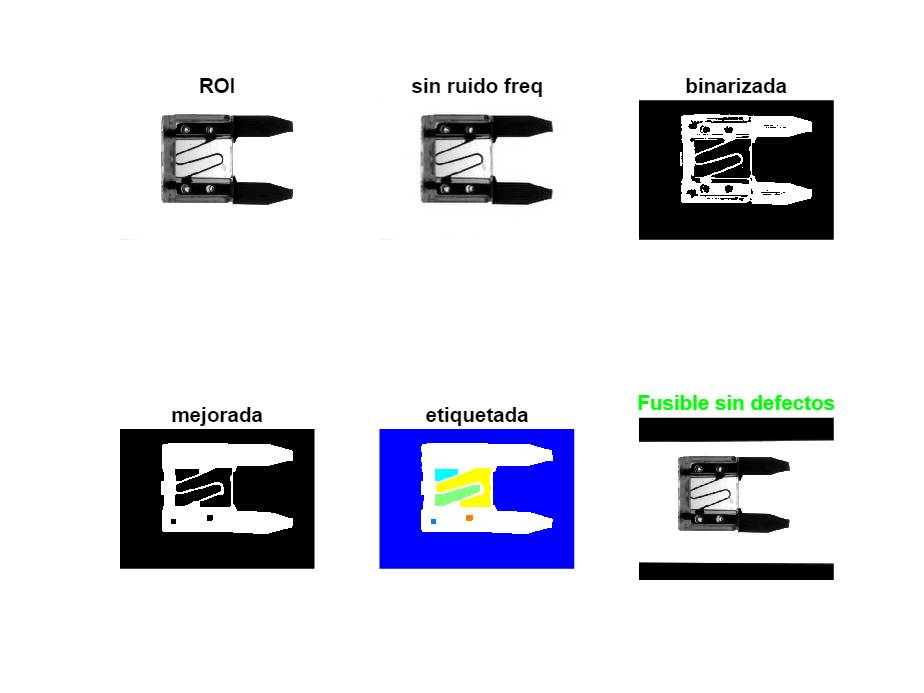

ans = logical
   1


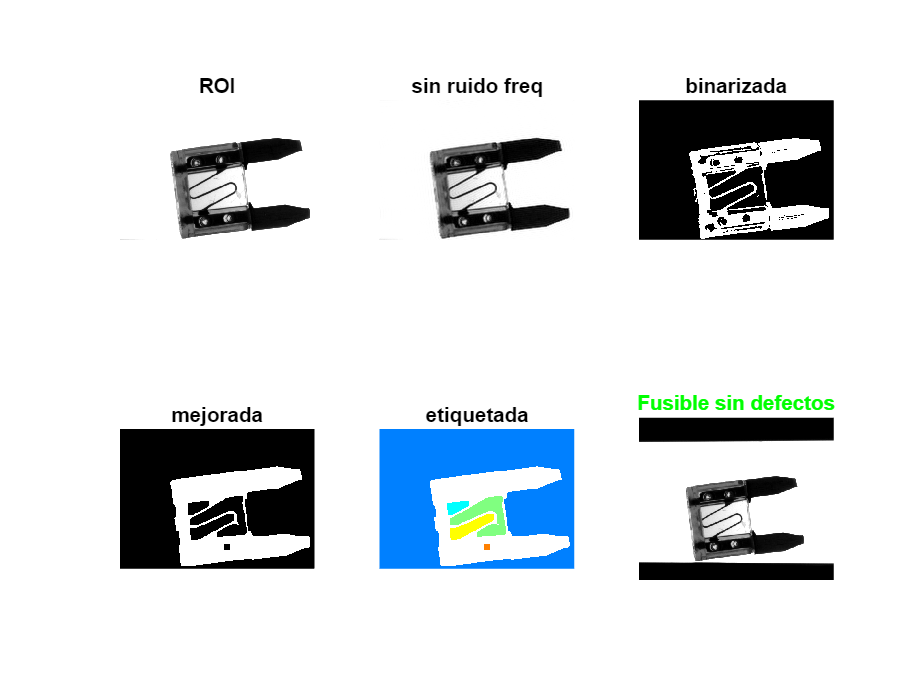

ans = logical
   1


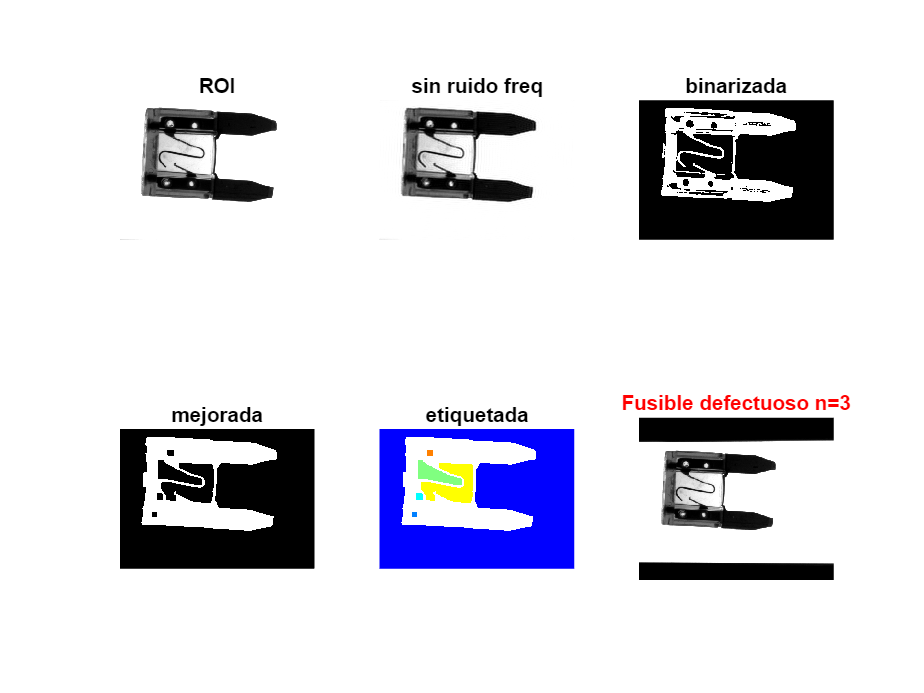

ans = logical
   0


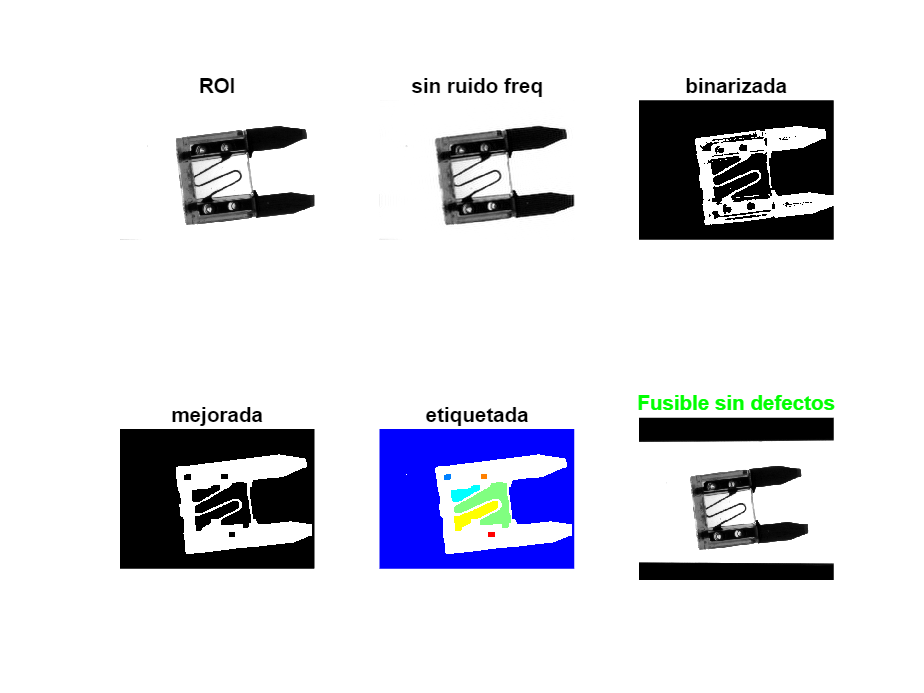

ans = logical
   1


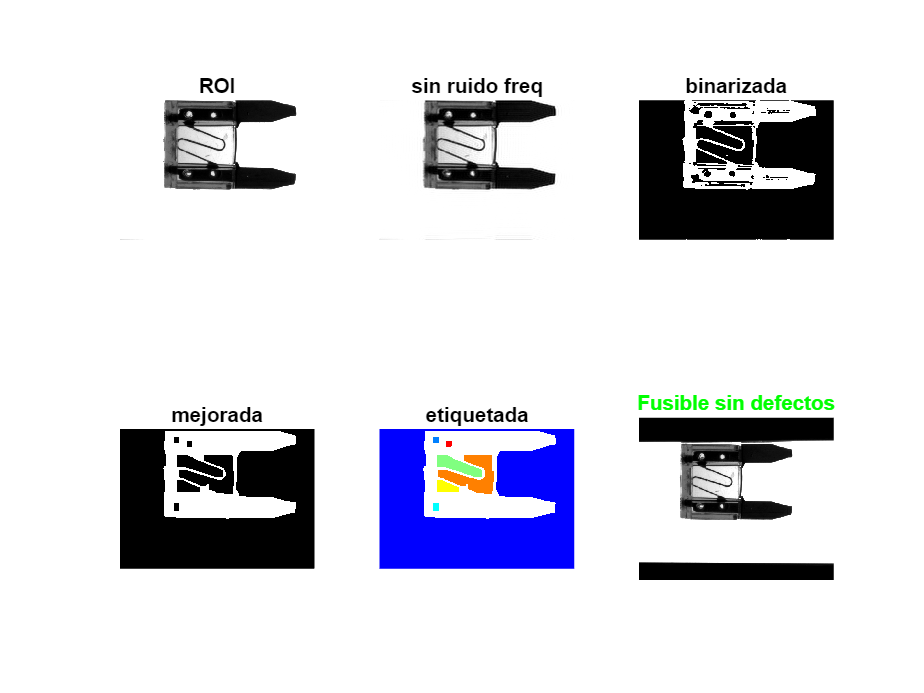

ans = logical
   1


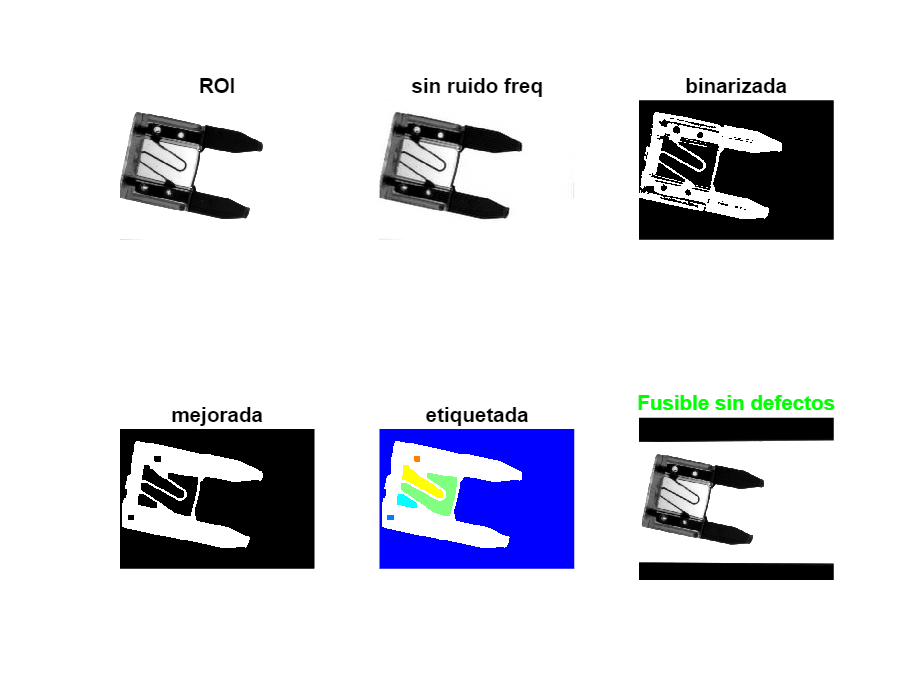

ans = logical
   1


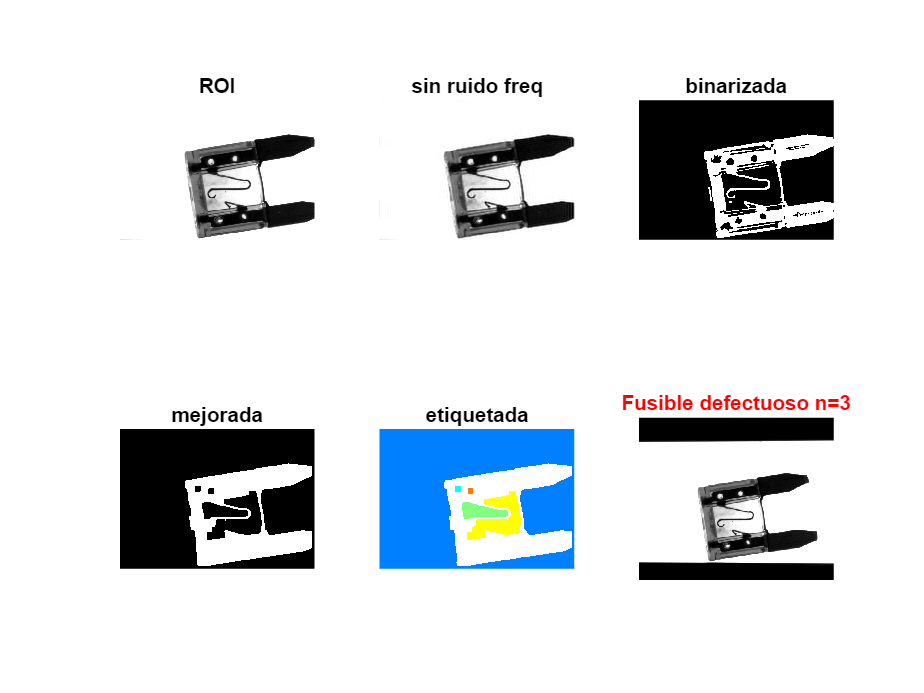

ans = logical
   0


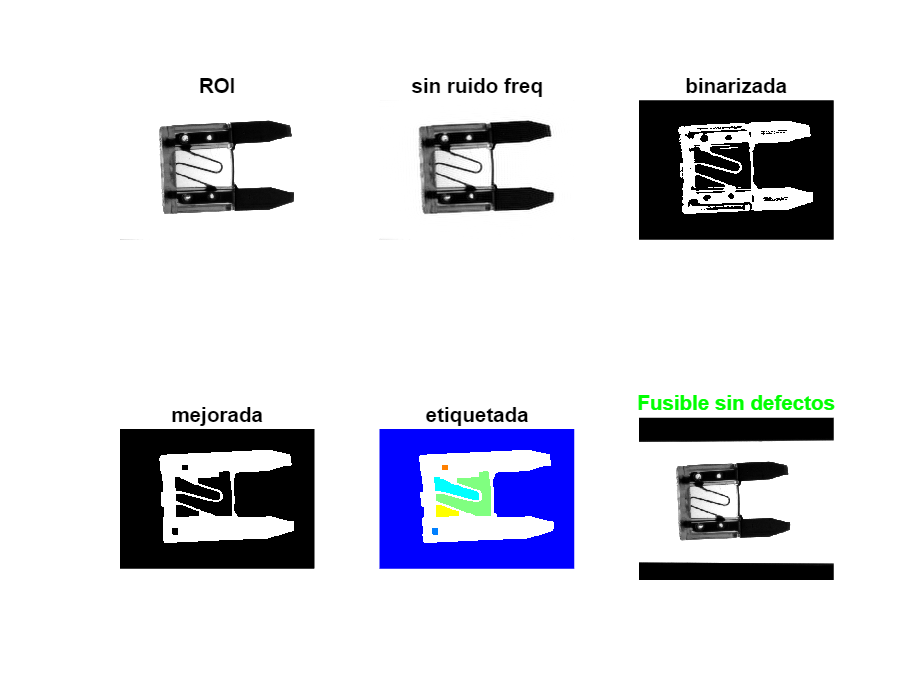

ans = logical
   1


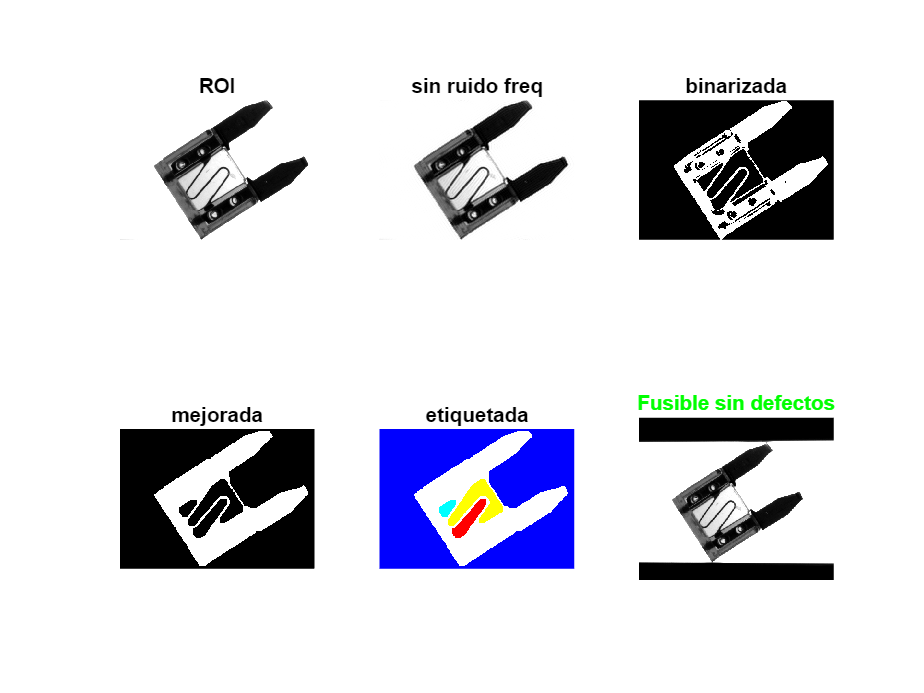

ans = logical
   1


ans = logical
   1


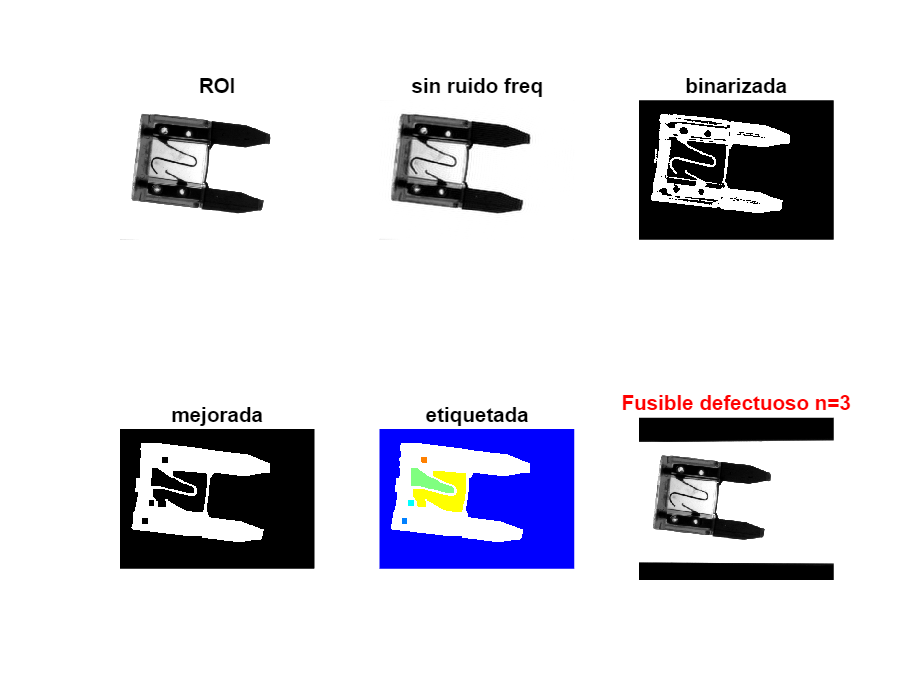

ans = logical
   0


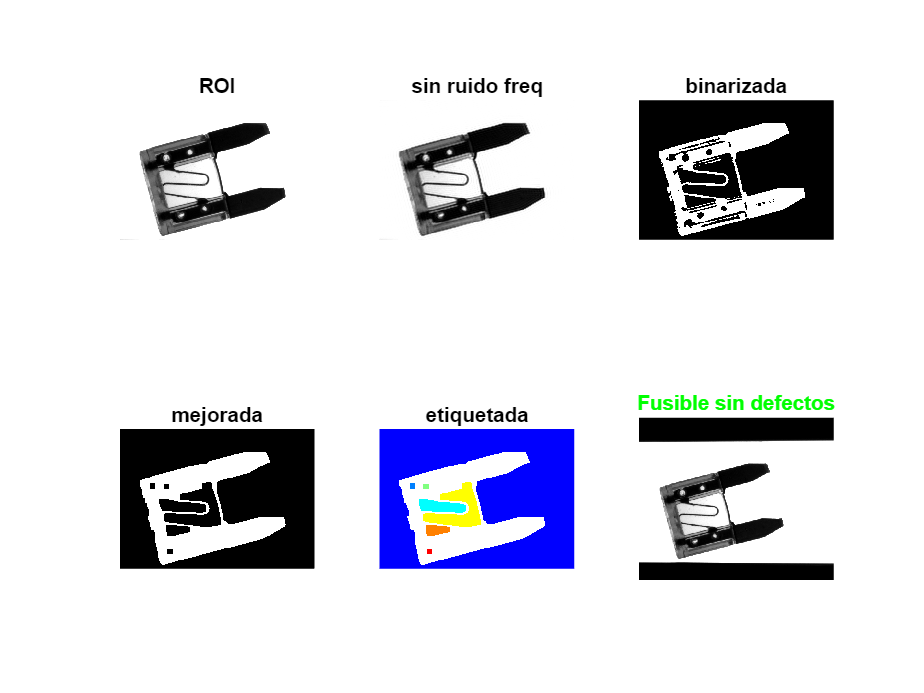

ans = logical
   1


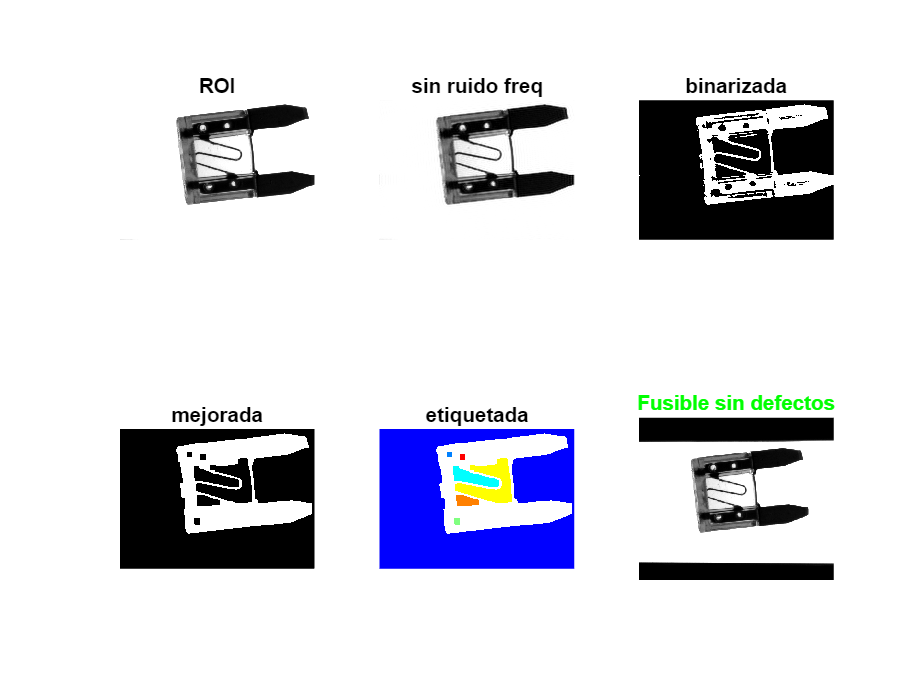

ans = logical
   1


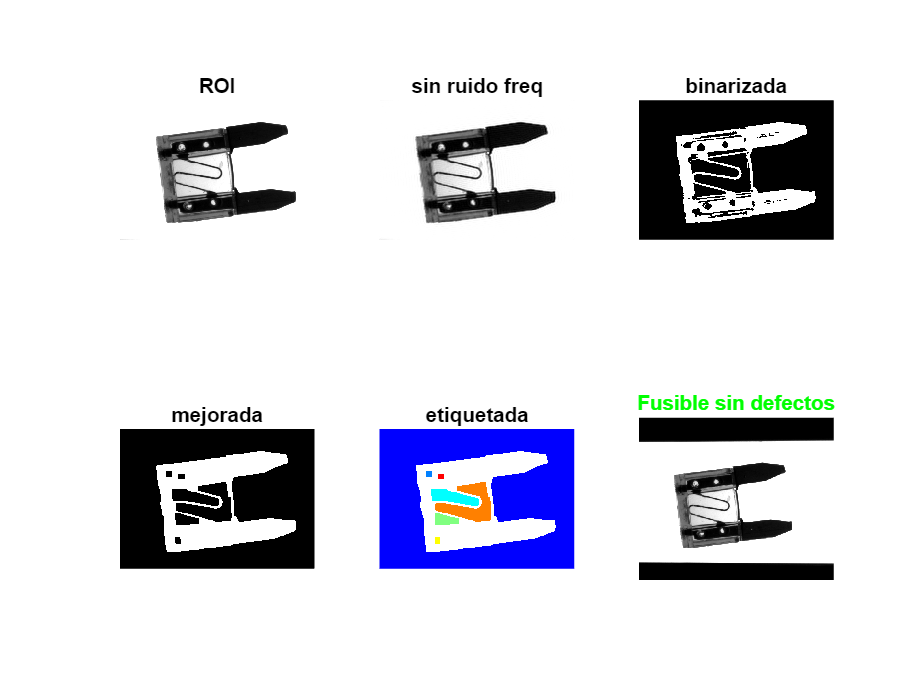

ans = logical
   1


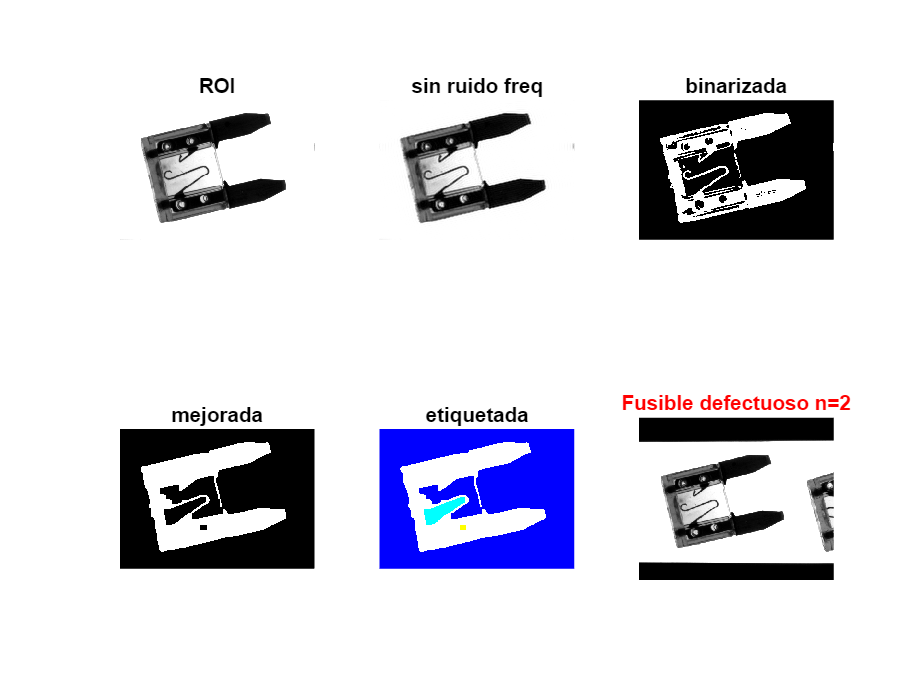

ans = logical
   0


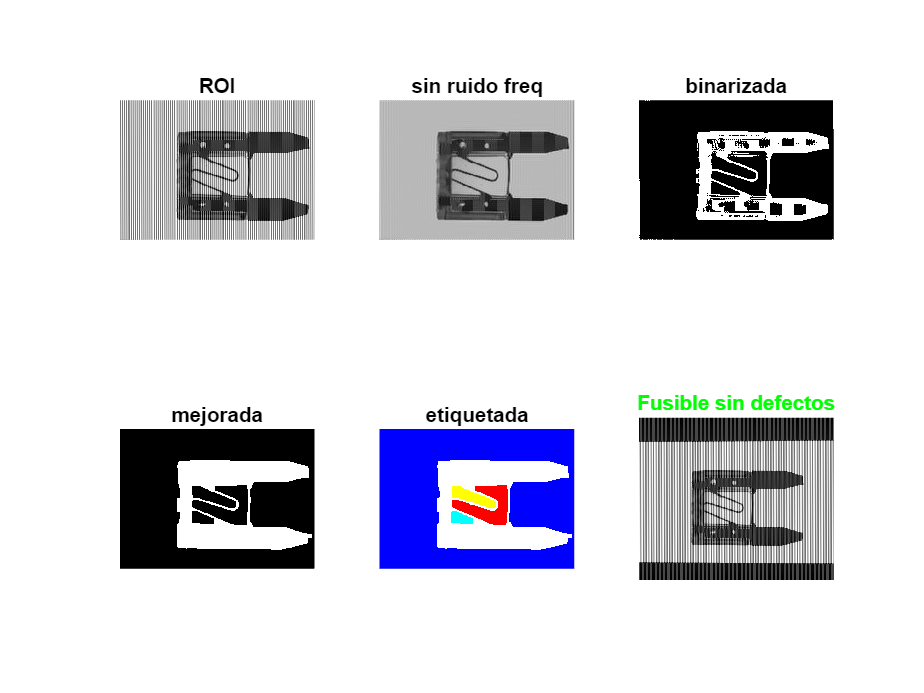

ans = logical
   1


for i=0:23
    if (not(i==22))
        FusibleEsCorrecto(imread(sprintf("../Imagenes/Fuse/Fuse %02d.tif", i)))
    end
end